# Lecture 4: Point Processing Operations

# Part 3: Contrast Stretching

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in the images folder of the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture4 - Point Processing

- pdf versions of the .mlx files are also available for those using GNU Octave

% clear workspace variables and close windows
clc, clearvars, close all;


I = imread('images/lena.jpg'); % read a low contrast image file
if(size(I,3) == 3) % convert to grayscale if not
    I = rgb2gray(I);
end

% check the initial dynamic range of the image (min and max values)
min(I(:))

ans = uint8
0

max(I(:))

ans = uint8
161

## Option 1: adjust contrast while displaying

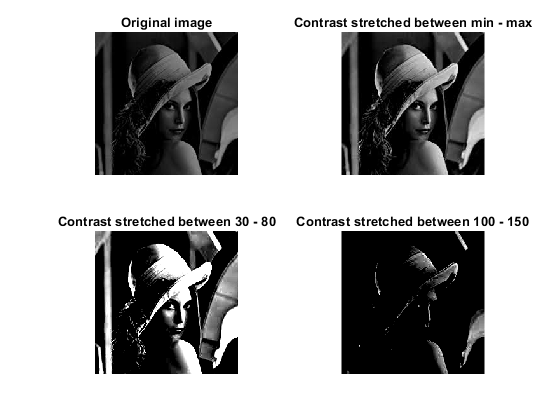

figure, subplot(2,2,1), imshow(I), title('Original image');
subplot(2,2,2), imshow(I, []), title('Contrast stretched between min - max');
subplot(2,2,3), imshow(I, [30 80]), title('Contrast stretched between 30 - 80');
subplot(2,2,4), imshow(I, [100 150]), title('Contrast stretched between 100 - 150');

## Option 2: using imadjust function

minlevel = double(min(I(:)))/255

minlevel = 0

maxlevel = double(max(I(:)))/255

maxlevel = 0.6314

I7 = imadjust(I,[minlevel maxlevel],[]);
min(I7(:))

ans = uint8
0

max(I7(:))

ans = uint8
255

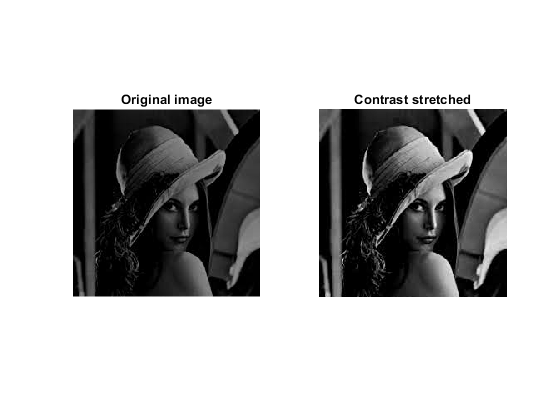

figure, subplot(1,2,1), imshow(I), title('Original image');
subplot(1,2,2), imshow(I7), title('Contrast stretched');